# Taller H infinito recuperación

Felipe Forero, Andrés Holguín, Andrés Morales

Departamento de Ingeniería Mecánica y Mecatrónica

Universidad Nacional de Colombia

Bogotá, Colombia

## Controlador SAS/CAS

## Controlador H inf

clear
close all
load("modelo_lin.mat");

En el taller que se entregó, a pesar de que se realizó la implementación de un diseño Hinf, se reconoce ciertos elementos faltantes o para mejorar en el desarrollo del mismo.

### Filtros

Para empezar, los diseños de los filtros W1, W2 y W3 para el sistema longitudinal y el lateral/direccional se realizaron con un valor de ganancia media sin justificar, ya que solo se realizó un proceso iterativo. Dicho esto, ahora se van a diseñar los filtros teniendo en cuenta las frecuencias de corte del filtro, es decir, cuando la ganancia es 3dB menor a la ganancia máxima, es decir, cuando la potencia de la señal de salida se ha reducido a aproximadamente el 50% y se considera que empieza a ocurrir efectivamente el filtrado.

####  Sistema Lateral/Direccional

W1_LD = makeweight(db2mag(23),[1 db2mag(20)],db2mag(-15)); %filtro pasa bajos
W2_LD = makeweight(db2mag(-28),[8500 db2mag(-8.2)],db2mag(-5.2)); %filtro pasa altos
W3_LD = makeweight(db2mag(-20),[500 db2mag(17)],db2mag(20)); %filtro pasa altos

Con estos nuevos filtros, se diseña una frecuencia de corte de 1 rad/s para el filtro pasa bajos W1, de 8500 rad/s para el filtro pasa altos W2, y de 500 rad/s para el filtro pasa altos W3.

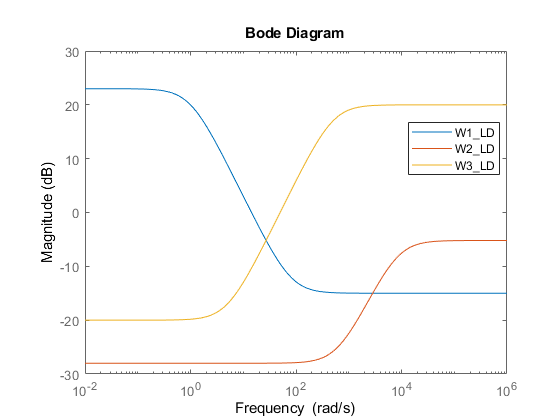

bodemag(W1_LD,W2_LD,W3_LD)
legend("Location","best")

#### Sistema Longitudinal

Para los filtros del sistema longitudinal se seleccionan frecuencias de corte de 0.07 rad/s para el filtro pasa bajos W1, de 36 rad/s para el filtro pasa altos W2, y de 2600 rad/s para el filtro pasa altos W3.

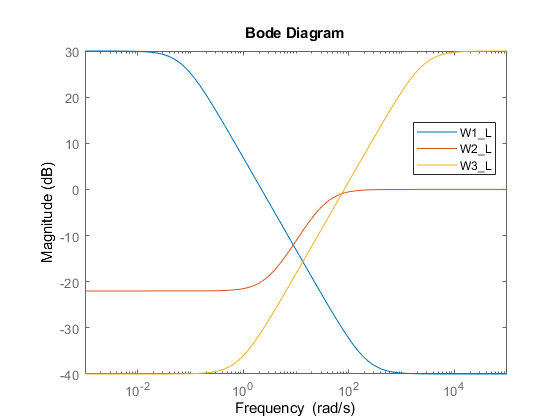

W1_L = makeweight(db2mag(30),[0.07 db2mag(27)],db2mag(-40)); %filtro pasa bajos
W2_L = makeweight(db2mag(-22),[36 db2mag(-3)],db2mag(0)); 
W3_L = makeweight(db2mag(-40),[2600 db2mag(27)],db2mag(30)); %filtro pasa altos
bodemag(W1_L,W2_L,W3_L)
legend("Location","best")

### Controladores Hinf

Ya con estos filtros redefinidos teniendo en cuenta adecuadamente las frecuencias de corte, se realiza la definición de los dos controladores a implementar. Esto se realiza al igual que en la entrega inicial.

#### Sistema Lateral/Direccional

Wp=makeweight(1,[10 0.1],0.01);
W1Phi= W1_LD;W1Psi= W1_LD;
W2Aileron= W2_LD;W2Rudder= W2_LD;
W3Phi=W3_LD;W3Psi=W3_LD;
Wn= 0.001;
systemnames= 'latmod Wp Wn W1Phi W1Psi W2Aileron W2Rudder W3Phi W3Psi';
inputvar= '[per; n; rPhi; rPsi; uAileron; uRudder]';
outputvar= '[W1Phi; W1Psi; W2Aileron; W2Rudder; W3Phi; W3Psi; -latmod(4) - Wn + rPhi;-latmod(5) - Wn + rPsi]';
input_to_latmod= '[-Wp + uAileron; -Wp + uRudder]';
input_to_Wn= '[n]';input_to_Wp     = '[per]';
input_to_W1Phi= '[-latmod(4) - Wn + rPhi]';input_to_W1Psi= '[-latmod(5) - Wn + rPsi]';
input_to_W2Phi= '[uAileron]';input_to_W2Psi= '[uRudder]';
input_to_W3Phi= '[latmod(4)]';input_to_W3Psi= '[latmod(5)]';
Planta = sysic;

ncont = 2; nmeas = 2; 
[K_LatDir,CL_LD,gamma_LD] = hinfsyn(Planta,nmeas,ncont);

A partir de este replanteamiento de controlador Hinf, se obtiene un gamma de $\gamma_{\textrm{LD}} =0\ldotp 7973$

%Función de Lazo abierto
L_LD = latmod*K_LatDir;
%Sistema en Lazo cerrado
Go_LD = feedback(L_LD,eye(2),[1,2],[4,5]);Go_LD.InputName={'aileron','rudder'};

Calculando el ancho de banda tanto para el control lateral y direccional, se determina que son de:

BWPhi = bandwidth(Go_LD(4,1))/2/pi

BWPhi = 5.7307

BWPsi = bandwidth(Go_LD(5,2))/2/pi

BWPsi = 4.8510

Unidades de rad/s.

#### Sistema Longitudinal

[K_Long,CL_L,gamma_L] = mixsyn(G_LongMod(1,1),W1_L,W2_L,W3_L);

A partir de este replanteamiento de controlador Hinf, se obtiene un gamma de $\gamma_L =0\ldotp 3919$

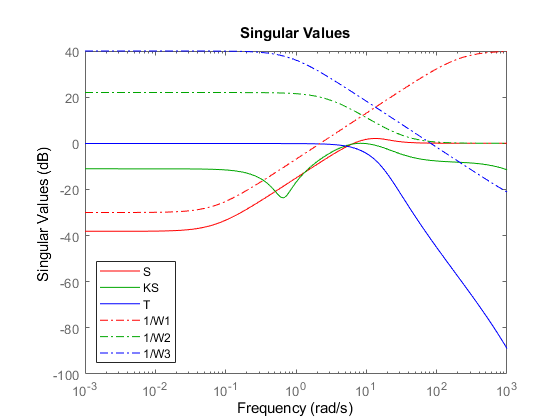

S_L = feedback(1,G_LongMod(1,1)*K_Long);
KS_L = K_Long*S_L;T_L = 1-S_L;
sigma(S_L,'r',KS_L,'g',T_L,'b',1/W1_L,'r-.',ss(1/W2_L),'g-.',1/W3_L,'b-.',{1e-3,1e3})
legend('S','KS','T','1/W1','1/W2','1/W3','Location','SouthWest')

OL_L=series(K_Long,G_LongMod(1,1));
GCL=feedback(OL_L,1);

GCL.InputName="elevator";

Calculando el ancho de banda  para el control longitudinal, se determina que es de:

bandwidth(GCL)/(2*pi)

ans = 1.3266

Unidades de rad/s.

### Análisis de velocidad

Ahora bien, algo que no se mencionó en la primera entrega, fue hacer análisis de la velocidad de los sistemas, ya que se debía mostrar que esta convergía a 0 para poder generar un set-point tracking adecuado.

#### Sistema ideal

**    Lateral/Direccional **

Para estos sistemas ideales que no contemplan ruido, incertidumbres ni perturbaciones, se realizan las gráficas del efecto paso en el alerón a la velocidad *p*, y del rudder a la velocidad *r *para el sistema Lateral/Direccional

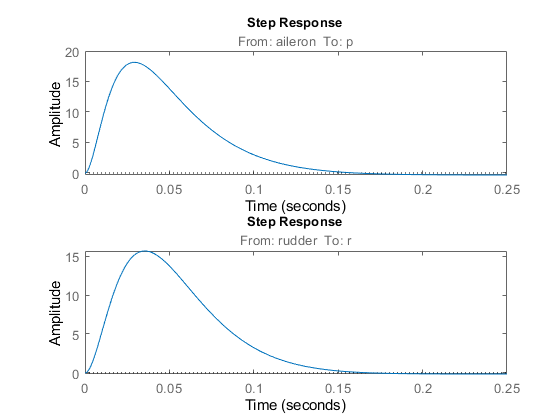


figure()
subplot(2,1,1)
step(Go_LD(2,1));
subplot(2,1,2)
step(Go_LD(3,2));

Como se puede ver en estas dos figuras, la velocidad de estos dos sistemas converge a un valor de cero, o cercano a este. En el caso de la velocidad *p, * esta no converge a 0 debido al acoplamiento que hay entre los sistemas lateral y direccional, sin embargo se evidencia que este valor no es significativo y que viene como propiedad intrínseca del sistema.

Dicho esto, se asume que en tiempos $>5\tau$ se logra converger a un estado estable de posición con el objetivo de cumplir con el set point tracking para este sistema.

**    Sistema Longitudinal **

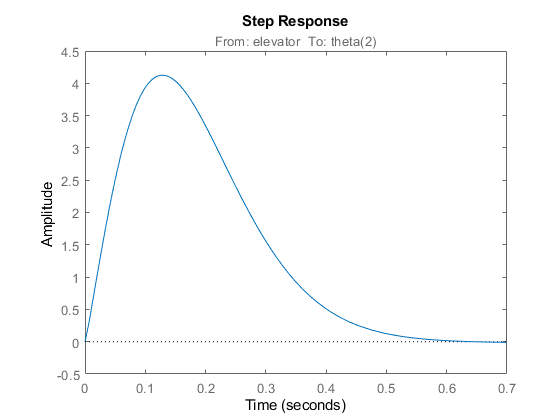

figure()
step(series(series(GCL,G_LongMod(1,1)^(-1)),G_LongMod(2,1)));

Como se puede ver en estas dos figuras, la velocidad de este sistema converge a un valor de cero, lo cual implica que en tiempos $>5\tau$ se logra converger a un estado al igual que en sistema anterior, lo que permite realizar el set-point tracking adecuadamente.

#### Sistema lineal con perturbaciones, incertidumbres y ruido

Para finalizar, se vuelven a hacer estas pruebas de velocidad pero para el sistema general en simulink de la planta completa. Se implementan los mismos set points que se realizaron en la entrega anterior.

Vals_Sim=sim("T1HinfFinal.slx");

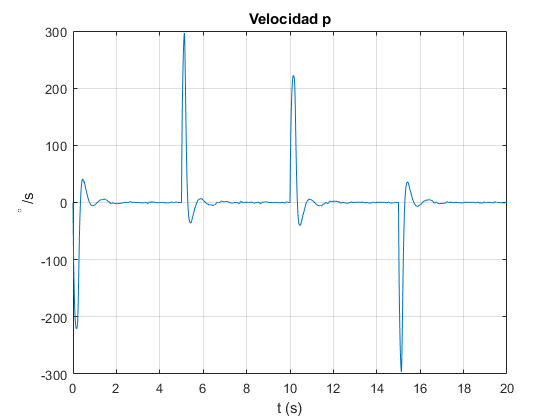

plot(Vals_Sim.vel.Time,Vals_Sim.vel.Data(:,2))
title("Velocidad p")
xlabel("t (s)");ylabel("^\circ /s");grid

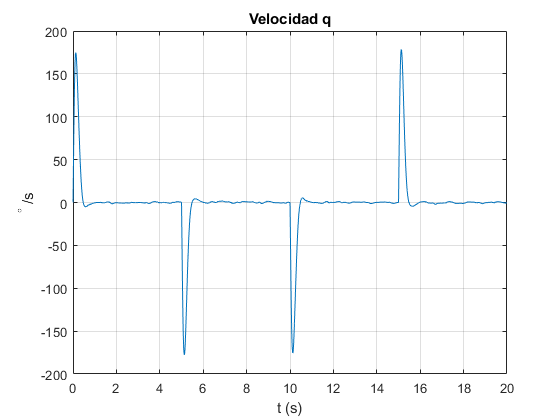


plot(Vals_Sim.vel.Time,Vals_Sim.vel.Data(:,1))
title("Velocidad q")
xlabel("t (s)");ylabel("^\circ /s");grid

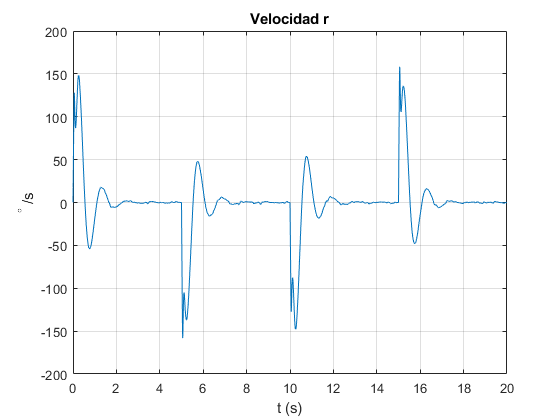


plot(Vals_Sim.vel.Time,Vals_Sim.vel.Data(:,3))
title("Velocidad r")
xlabel("t (s)");ylabel("^\circ /s");grid

Como se puede evidenciar, estos valores tienen picos en los saltos de referencia de posición, y luego se reducen hasta oscilar cercano a velocidad nula. Para analizar un poco mejor estos valores, se realiza una selección del intervalo de tiempo entre los 18s y 20s para analizar esta velocidad.

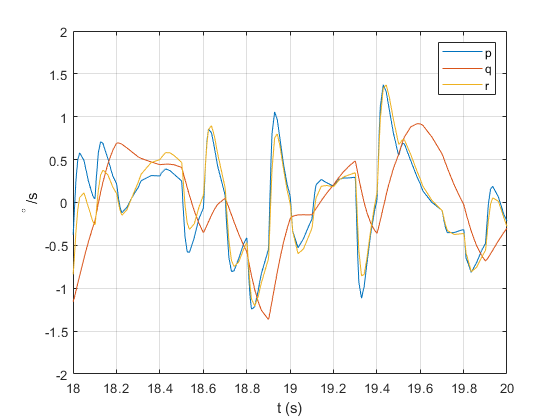

plot(Vals_Sim.vel.Time,Vals_Sim.vel.Data(:,2))
hold on
plot(Vals_Sim.vel.Time,Vals_Sim.vel.Data(:,1))
plot(Vals_Sim.vel.Time,Vals_Sim.vel.Data(:,3))
hold off
xlabel("t (s)");ylabel("^\circ /s")
legend("p","q","r");axis([18 20 -2 2]);grid

Como se puede evidenciar, los efectos externos están generando osculaciones de velocidad acotadas entre $V\in \left\lbrack -1\ldotp 5^{\circ } \;1\ldotp 5^{\circ } \right\rbrack s^{-1}$, lo cual es entendible debido a las condiciones del sistema.

Con todo y lo anterior, se establece que la velocidad efectivamente logra converger a valores cercanos y oscilantes a 0, los cuales son producidos por la correción de velocidad para lograr mitigar los efectos de factores externos del sistema.